# Quadruped's spine optimizer

Script going to find best stiffness, damphing and equilibrium position spine robot for ready trajectory legs. Write name files with trajectory and variables 

clc; clear global;

addpath(genpath('Quadruped robot optimization hybrid optimize'));
robotParameters;
path = 'PD_optimizedData_19Mar22_1625_troting';

mdlName = 'QR_Unitree_with_spine'; % Main model
open_system(mdlName);

gfh

scalingFactor = 2;

accelFlag = false;
parallelFlag = false;  

poulation_size = 20;
p0 = zeros(poulation_size,3);

opts = optimoptions('ga');
opts.Display = 'iter';
opts.MaxGenerations = 5;
opts.PopulationSize = poulation_size;
opts.PlotFcn = {@gaplotbestf, @gaplotexpectation}; 
opts.UseParallel = parallelFlag;
opts.InitialPopulationMatrix = p0;

% opts.MutationFcn = @mutationadaptfeasible;
% opts.HybridFcn = {@patternsearch,psOptions};

% [equilibrium position, stiffness, damphing]
upperBnd = [pi/6, 500, 100]/scalingFactor; 
lowerBnd = [-pi/6, 0, 0]/scalingFactor;
% doSpeedupTasks;

dfg

costFcn = @(p)CostFuncOptimizeSpine(p,scalingFactor,path,mdlName);
disp(['Running optimization. Population: ' num2str(opts.PopulationSize) ...
       ', Max Generations: ' num2str(opts.MaxGenerations)])

Running optimization. Population: 20, Max Generations: 5



Single objective optimization:
3 Variable(s)
3 Integer variable(s)

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1               40      -2.082e-06      -2.082e-06        0
    2               58      -2.082e-06      -2.082e-06        1
    3               76      -2.082e-06      -2.082e-06        2
    4               94      -2.082e-06      -2.082e-06        3
    5              112      -2.082e-06      -2.082e-06        4


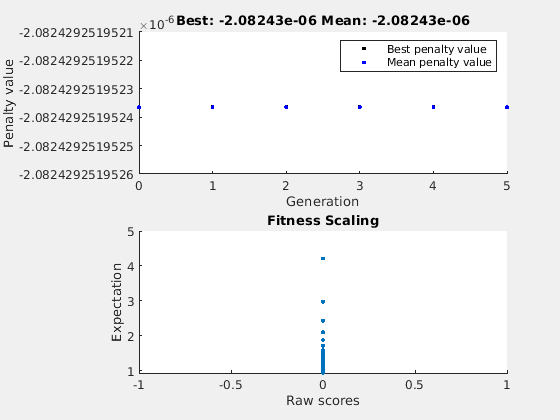

Optimization terminated: maximum number of generations exceeded.



[pFinal,reward] = ga(costFcn,3,[],[],[],[], ... 
                      lowerBnd,upperBnd,[],1:3,opts);


disp(['Final reward function value: ' num2str(-reward)])

Final reward function value: 2.0824e-06



pScaled = scalingFactor*pFinal;
spine_position = pScaled(1);
spine_spring_stiff = pScaled(2);
spine_damphing_coeff = pScaled(3);

outFileName = ['ResultOptimizeSpine/' path '_spine_optimize_' datestr(now,'ddmmmyy_HHMM')];
save(outFileName,'reward','spine_position','spine_spring_stiff','spine_damphing_coeff');
delete(gcp('nocreate'));